## cleaning the data

ChinaDataUnclean1.total = ChinaDataUnclean1.Coal + ChinaDataUnclean1.Oil + ChinaDataUnclean1.Gas + ChinaDataUnclean1.Cement + ChinaDataUnclean1.Flaring + ChinaDataUnclean1.Other

ChinaDataUnclean1 = 117×16 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal     Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    total 
    _______    ________________    _____    ____    ______    ______    ___    ___    ______    _______    _____    _________    _____    _____    _____    ______

     China           CHN            156     1907    19.894    19.894     0      0       0       


chn = ChinaDataUnclean1

chn = 117×16 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal     Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    total 
    _______    ________________    _____    ____    ______    ______    ___    ___    ______    _______    _____    _________    _____    _____    _____    ______

     China           CHN            156     1907    19.894    19.894     0      0       0          0         0


n = height(chn)

n = 117

train_size = floor(0.96 * n);

trainIdx = false(n, 1);
testIdx = false(n, 1);

trainIdx(1:train_size) = true;
testIdx(train_size + 1:end) = true;

chnTrain = chn(trainIdx, :);
chnTest = chn(testIdx, :);

disp(['Training set size: ', num2str(sum(trainIdx))]);

Training set size: 112


disp(['Test set size: ', num2str(sum(testIdx))]);

Test set size: 5


## visualize current

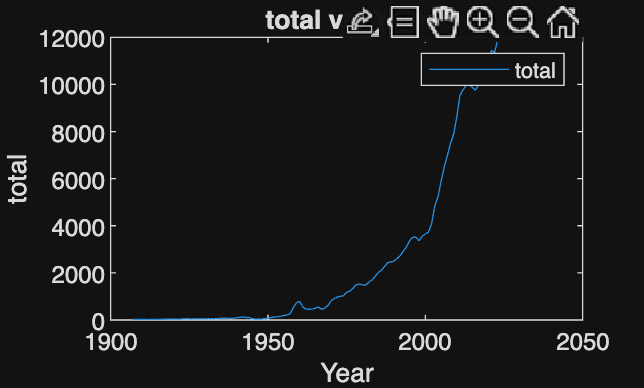

% Create plot of ChinaDataUnclean1.Year and ChinaDataUnclean1.total
h = plot(ChinaDataUnclean1,"Year","total","DisplayName","total");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("total")
title("total vs. Year")
legend

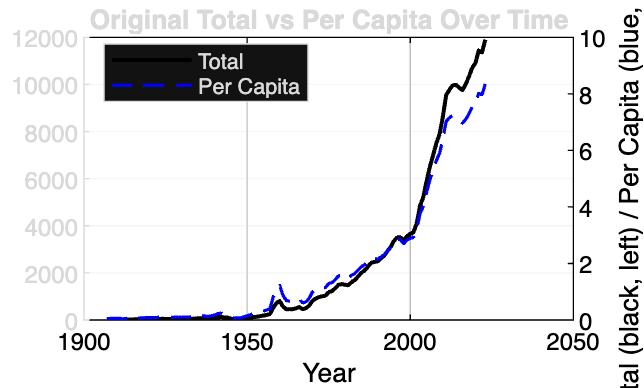

% --- Visualize original data ---
figure('Color','w');
plot(ChinaDataUnclean1.Year, ChinaDataUnclean1.Total, 'k-', 'LineWidth', 1.5); hold on;
yyaxis right
plot(ChinaDataUnclean1.Year, ChinaDataUnclean1.PerCapita, 'b--', 'LineWidth', 1.2);
xlabel('Year');
ylabel('Total (black, left) / Per Capita (blue, right)');
title('Original Total vs Per Capita Over Time');
legend('Total','Per Capita','Location','best');
grid on; box on;
set(gca,'Color','w','XColor','k','YColor','k');

## make data stationary

%% taking the log
chnTrain.log = log(chnTrain.Total);

% make data stationary

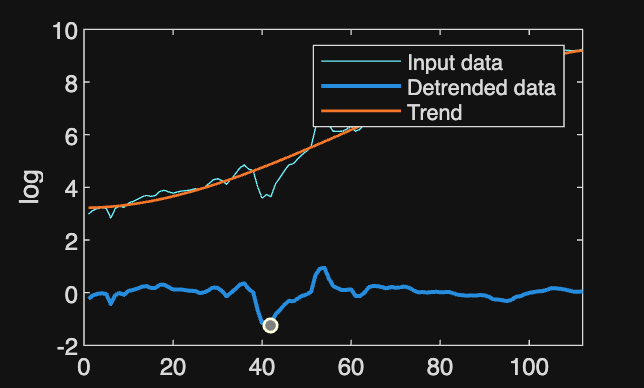

% Remove trend from input data
cubicTrend = detrend(chnTrain,3,DataVariables="log");

% Display results
figure
plot(chnTrain.log,SeriesIndex=6,DisplayName="Input data")
hold on
plot(cubicTrend.log,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(chnTrain.log-cubicTrend.log,SeriesIndex=2,LineWidth=1,DisplayName="Trend")
hold off
legend
ylabel("log")

% Remove trend from input data
cubicTrend = detrend(chnTrain, 3, DataVariables = "log");

% Save detrended data
chnTrain.cubeDetrended = cubicTrend.log

chnTrain = 112×18 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal     Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    total      log      cubeDetrended
    _______    ________________    _____    ____    ______    ______    ___    ___    ______    _______    _____    _________    _____    _____    _____    ______    ______    _______


% Save cubic trend to model
chnTrain.cubicTrend = chnTrain.log - cubicTrend.log

chnTrain = 112×19 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal     Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    total      log      cubeDetrended    cubicTrend
    _______    ________________    _____    ____    ______    ______    ___    ___    ______    _______    _____    _________    _____    _____    _____    ______    ___


% Extracted cubic trend plot

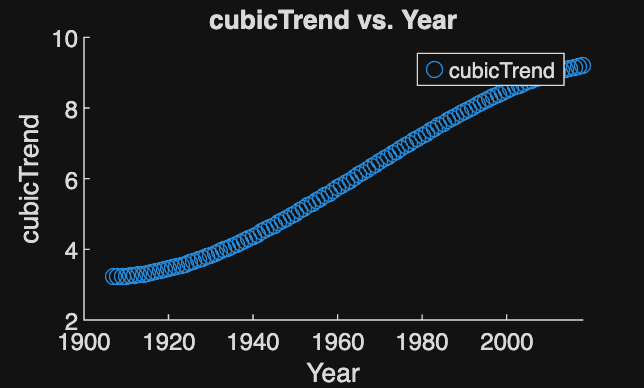

% Create scatter of chnTrain.Year and chnTrain.cubicTrend
cubicTrend = scatter(chnTrain,"Year","cubicTrend","DisplayName","cubicTrend");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("cubicTrend")
title("cubicTrend vs. Year")
legend


% Cubic DETRENDED data

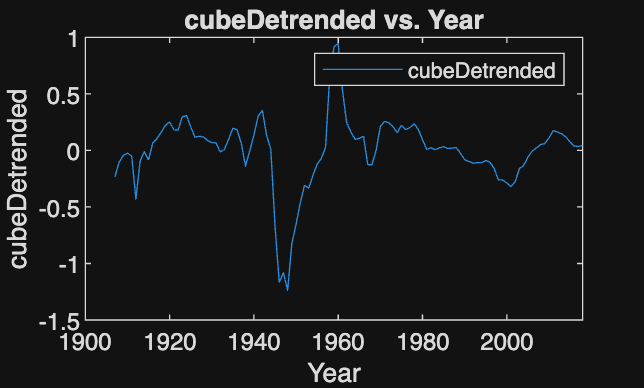

% Create plot of chnTrain.Year and chnTrain.cubeDetrended
cubicDetrended = plot(chnTrain,"Year","cubeDetrended","DisplayName","cubeDetrended");

% Add xlabel, ylabel, title, and legend
xlabel("Year")
ylabel("cubeDetrended")
title("cubeDetrended vs. Year")
legend

CubicMdl = fit(chnTrain.Year, chnTrain.cubicTrend, 'poly3');

## ACF & PCF graphs

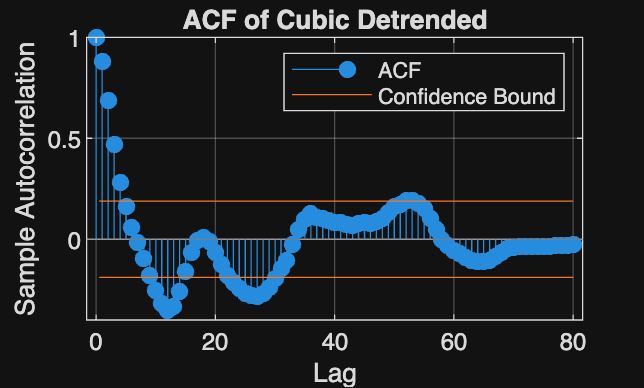

% I used the econometric app
figure;

subplot(1,1,1);
autocorr(chnTrain.cubeDetrended, 'NumLags', 80);
title('ACF of Cubic Detrended');

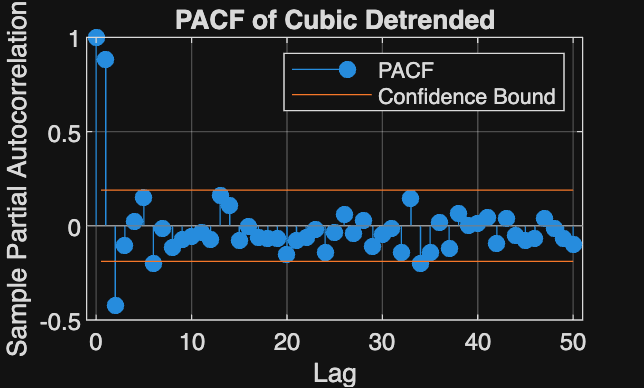


figure;
subplot(1,1,1);
parcorr(chnTrain.cubeDetrended, 'NumLags', 50);
title('PACF of Cubic Detrended');

## Model Selection + Forecasting

frcst = table;
frcst.Year = chnTest.Year;
prevIdx = height(chnTrain)

prevIdx = 112


frcst.Idx = (prevIdx+1:prevIdx+height(frcst))'

frcst = 5×2 table
    Year    Idx
    ____    ___

    2019    113
    2020    114
    2021    115
    2022    116
    2023    117



frcstHorizon = height(frcst)

frcstHorizon = 5


frcst.CubicFrcst = feval(CubicMdl, frcst.Idx);

% find best p and q
p_range = 0:5;
q_range = 0:5;

% store model results
results = [];

% Grid search on residuals
for p = p_range
    for q = q_range
        try
            % Fit ARIMA model with d=0
            model = arima(p, 0, q);
            fit = estimate(model, chnTrain.cubeDetrended, 'Display', 'off');
            
            % Get log-likelihood
            [~, ~, logL] = infer(fit, chnTrain.cubeDetrended);
            
            numParams = p + q;
            if fit.Constant ~= 0 
                numParams = numParams + 1;
            end
            
            n = length(chnTrain.cubeDetrended);
            
            aic = -2*logL + 2*numParams;
            bic = -2*logL + numParams*log(n);
            
            % Store results: [p, q, AIC, BIC, LogLikelihood]
            results = [results; p, q, aic, bic, logL];
            
        catch ME
            fprintf('Failed to fit ARIMA(%d,0,%d): %s\n', p, q, ME.message);
            continue;
        end
    end
end

% Convert to table for easier viewing
resultsTable = array2table(results, ...
    'VariableNames', {'p', 'q', 'AIC', 'BIC', 'LogLikelihood'});

% Sort by AIC (lower is better)
resultsTable = sortrows(resultsTable, 'AIC');

% Display top 10 models
disp('Top 10 models by AIC:');

Top 10 models by AIC:


disp(resultsTable(1:min(10, height(resultsTable)), :));

    p    q      AIC        BIC      LogLikelihood
    _    _    _______    _______    _____________

    2    5    -134.45     -112.7       75.226    
    3    4    -133.56    -111.81       74.778    
    4    5    -133.31    -106.13       76.656    
    4    2     -131.7    -112.67       72.849    
    5    5    -130.12    -100.22        76.06    
    5    4    -130.09     -102.9       75.043    
    5    2    -130.05    -108.31       73.027    
    5    3    -129.59    -105.13       73.797    
    4    4    -129.22    -104.75       73.608    
    1    3    -129.14    -115.54       69.568    




% AIC and BIC
[~, idx_aic] = min(resultsTable.AIC);
[~, idx_bic] = min(resultsTable.BIC);

fprintf('\n=== BEST MODELS ===\n');


=== BEST MODELS ===



fprintf('Best by AIC: ARIMA(%d,0,%d) - AIC = %.4f\n', ...
    resultsTable.p(idx_aic), resultsTable.q(idx_aic), resultsTable.AIC(idx_aic));

Best by AIC: ARIMA(2,0,5) - AIC = -134.4510



fprintf('Best by BIC: ARIMA(%d,0,%d) - BIC = %.4f\n', ...
    resultsTable.p(idx_bic), resultsTable.q(idx_bic), resultsTable.BIC(idx_bic));

Best by BIC: ARIMA(2,0,0) - BIC = -120.2897



% Fit the best model (by BIC)
best_p = resultsTable.p(idx_bic);
best_q = resultsTable.q(idx_bic);

fprintf('\nFitting best model: ARIMA(%d,0,%d)...\n', best_p, best_q);


Fitting best model: ARIMA(2,0,0)...



bestModel = arima(best_p, 0, best_q);
bestARIMAfit = estimate(bestModel, chnTrain.cubeDetrended, 'Display', 'off');

% Display fitted model
disp(bestARIMAfit);

  arima with properties:

     Description: "ARIMA(2,0,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 2
               D: 0
               Q: 0
        Constant: 0.000890616
              AR: {1.25881 -0.425198} at lags [1 2]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.0176278


## Forecasting for next 5 years

putting a pin in the arima parameter search --> will use (2, 0, 1) respectively

frcst.ARIMABest = forecast(bestARIMAfit, frcstHorizon, chnTrain.cubeDetrended);
disp(bestARIMAfit);

  arima with properties:

     Description: "ARIMA(2,0,0) Model (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 2
               D: 0
               Q: 0
        Constant: 0.000890616
              AR: {1.25881 -0.425198} at lags [1 2]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.0176278



% Untransform
frcst.Co2Forecast = exp(frcst.ARIMABest + frcst.CubicFrcst);

## Calculating RMSE

% Calculate RMSE
%remove 2019 2020
E = rmse(frcst.Co2Forecast(3:5, :), chnTest.Total(3:5, :));

% Display the result
disp(['The RMSE is: ', num2str(E)]);

The RMSE is: Inf


## Plot

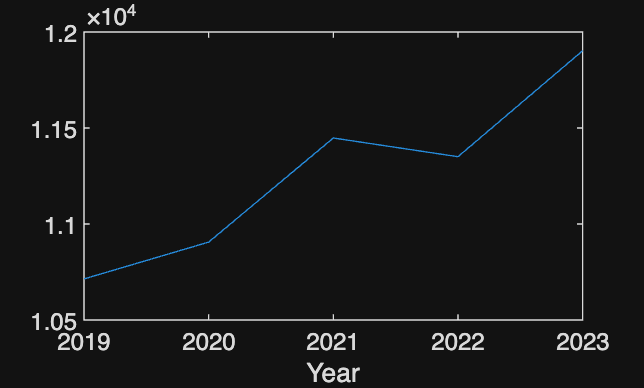

figure;
% plot(usa, "Year", "Total")
% hold on
plot(chnTest, "Year", "Total")
hold on
plot(frcst,"Year","Co2Forecast")
hold off

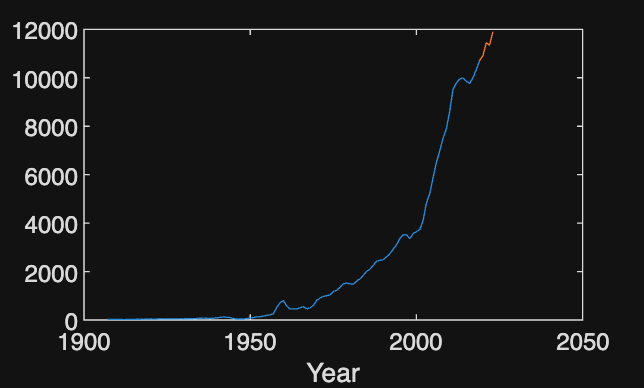

figure;
plot(chn, "Year", "Total")
hold on
plot(chnTest, "Year", "Total")
hold on
plot(frcst,"Year","Co2Forecast")
hold off